# TF estimating, and PID Tuning Script

## Importing the table

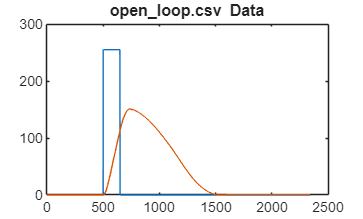

step_pwm = readtable("open_loop.csv");
figure;
plot(step_pwm.time, step_pwm.pwmValue, step_pwm.time, step_pwm.position);
title("open\_loop.csv Data");

T = readtable("open_loop.csv");

## Removing offset

t_raw = T.time(:) / 1000;         % seconds (time is in ms)
u_raw = T.pwmValue(:);            % PWM command (0..255)
y_raw = T.position(:);            % encoder counts

% Ensure column vectors + sorted time
[t_raw, idx] = sort(t_raw);
u_raw = u_raw(idx);
y_raw = y_raw(idx);

%% 2) Resample to uniform Ts
Ts = median(diff(t_raw));          % ~0.001 s
t = (t_raw(1):Ts:t_raw(end))';

% Input as zero-order hold, output as linear interpolation
u = interp1(t_raw, u_raw, t, "previous", "extrap");
y = interp1(t_raw, y_raw, t, "linear",   "extrap");

% optional: convert counts -> radians (set your encoder CPR!)
% If you don't know CPR yet, keep y in counts for now.
CPR = 2048;                        % <-- CHANGE (counts per revolution)
y = (2*pi/CPR) * y;                % radians

% trim to a clean window (optional but helps)
% Include a bit before the pulse and enough time after to see ring-down
tStart = 0.0;
tEnd   = t(end);
keep = (t >= tStart) & (t <= tEnd);

t = t(keep);
u = u(keep);
y = y(keep);

%% detrend / remove offsets
u = u - u(1);
y = y - y(1);

% If you want input in "duty" instead of 0..255:
u = u / 255;

% build iddata
data = iddata(y, u, Ts, "TimeUnit","s");

## Estimating, curve fitting

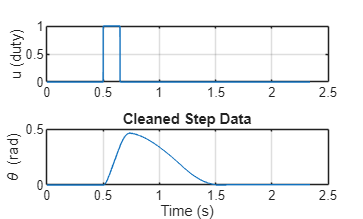

% Plots
figure; subplot(2,1,1); plot(t,u); grid on; ylabel("u (duty)");
subplot(2,1,2); plot(t,y); grid on; ylabel("\theta (rad)"); xlabel("Time (s)");
title("Cleaned Step Data");

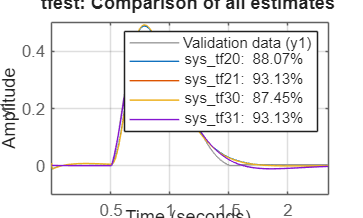


% Estimate models
sys_tf20 = tfest(data, 2, 0, 'InputDelay', 0.003);
sys_tf21 = tfest(data, 2, 1, 'InputDelay', 0.003);
sys_tf30 = tfest(data, 3, 0, 'InputDelay', 0.003);
sys_tf31 = tfest(data, 3, 1, 'InputDelay', 0.003);

figure; compare(data, sys_tf20, sys_tf21,sys_tf30,sys_tf31); grid on;
title("tfest: Comparison of all estimates");

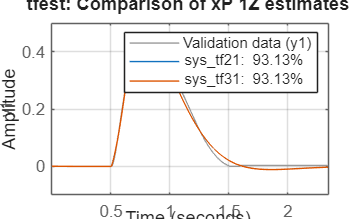


figure; compare(data, sys_tf21, sys_tf31); grid on;
title("tfest: Comparison of xP 1Z estimates");

## Residuals

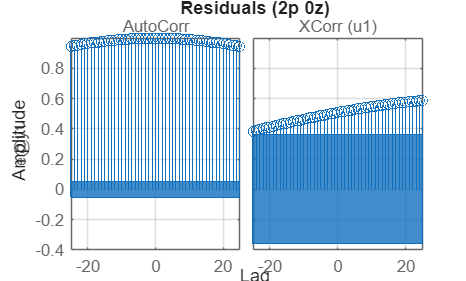

figure; resid(data, sys_tf20); grid on; title("Residuals (2p 0z)");

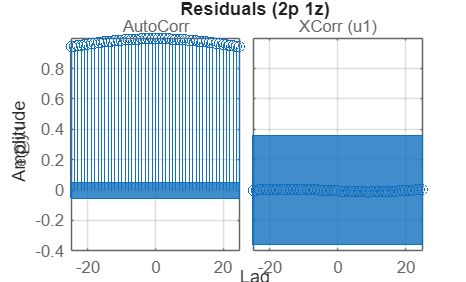

figure; resid(data, sys_tf21); grid on; title("Residuals (2p 1z)");

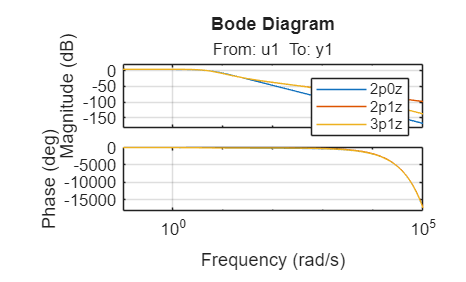

figure; bode(sys_tf20, sys_tf21, sys_tf31); grid on; legend("2p0z","2p1z", "3p1z");

## Display selected system

disp("Select 2 poles 1 zero as best fit model");

Select 2 poles 1 zero as best fit model


sys_tf21


sys_tf21 =
 
  From input "u1" to output "y1":
                     1.276 s + 32.18
  exp(-0.003*s) * ---------------------
                  s^2 + 6.905 s + 20.39
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 1
   Number of free coefficients: 4
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 93.13%                   
FPE: 0.0001159, MSE: 0.0001153                   
 
Model Properties


disp('Damping / natural frequencies for 2p1z model:');

Damping / natural frequencies for 2p1z model:


damp(sys_tf21)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -3.45e+00 + 2.91e+00i     7.64e-01       4.52e+00         2.90e-01    
 -3.45e+00 - 2.91e+00i     7.64e-01       4.52e+00         2.90e-01    


## Plot selected system

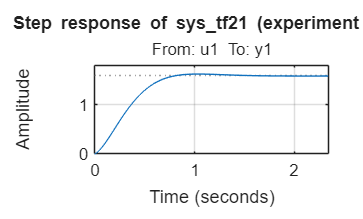

figure;
step(sys_tf21, t);
grid on;
title('Step response of sys\_tf21 (experiment time)');

## Tuning the Gains

G = sys_tf21;     % use your chosen plant model
H = 1;            % unity feedback

% Target RCGs
Ts_target  = 0.10;   % seconds
Tr_target = 0.05;    % seconds
OSu_target = 10;     % percent overshoot
Ess_target = 1;      % percent steady-state error

% Derivative filter pole (must be negative)
p = -200;            % try -80 to -800 depending on noise / aggressiveness

% Initial guess (seed)
% using pid tune as a starting point
try
    C0 = pidtune(G, "PID");  % Control System Toolbox
    KIN.K  = 1;
    KIN.Kp = C0.Kp;
    KIN.Ki = C0.Ki;
    KIN.Kd = C0.Kd;
catch
    % fallback guess
    KIN.K  = 1;
    KIN.Kp = 1;
    KIN.Ki = 1;
    KIN.Kd = 0.01;
end

% Run tuner
Kbest = heurRCGTune_PID(KIN, Ts_target, Tr_target, OSu_target, Ess_target, p, G, H);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           4    2.977446e+04     0.000e+00     1.000e+00     0.000e+00     1.652e+04  
Objective function returned Inf; trying a new point...
    1          19    2.627388e+04     0.000e+00     1.977e-02     4.366e+01     3.208e+04  
Objective function returned Inf; trying a new point...
    2          36    5.614053e+03     0.000e+00     9.689e-03     5.024e+00     1.567e+07  
    3          44    4.224178e+03     0.000e+00     2.401e-01     1.362e+00     4.409e+07  
Objective function returned Inf; trying a new point...
    4          63    4.176553e+03     0.000e+00     4.748e-03     7.163e-01     3.335e+07  
Objective function returned Inf; trying a new point...
    5         101    4.176433e+03     0.000e+00     5.412e-06     1.217e-04     3.581e+07  
    6         105    1.246220e+02     0.000e+0


Kp = Kbest(1); Ki = Kbest(2); Kd = Kbest(3);
fprintf('\nTUNED GAINS:\nKp = %.6g\nKi = %.6g\nKd = %.6g\n', Kp, Ki, Kd);


TUNED GAINS:
Kp = 15
Ki = 23.113
Kd = 0.742078


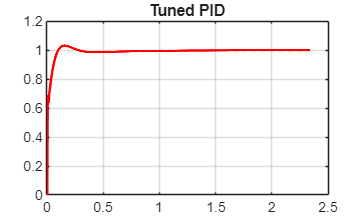


% Build controller + show closed-loop step
s = tf('s');
D   = Kp + Ki/s + Kd * (-p*s/(s - p));     % same form as tuner
Tcl = feedback(G*D, H);

% Use 0-based time axis
t_plot = t - t(1);

% Get step response
y_found = step(Tcl, t_plot);

% Plotting tuned PID
figure;
plot(t_plot, y_found, '-r', 'LineWidth', 1.5);
title('Tuned PID');
grid on;


% Step response metrics
info = stepinfo(Tcl, 'RiseTimeLimits', [0 1]);
Ess  = abs(1 - dcgain(Tcl))*100;
fprintf('Closed-loop metrics: Ts=%.4f s, OS=%.2f%%, Tr=%.4f s, Ess=%.3f%%\n', ...
    info.SettlingTime, info.Overshoot, info.RiseTime, Ess);

Closed-loop metrics: Ts=0.2103 s, OS=3.05%, Tr=0.0990 s, Ess=0.000%


## IGNORE: Testing with different gains

%{
    Kp = 0.000120601
    Ki = 4.43077
    Kd = 0
%}
Kp = 71.1451

Kp = 71.1451

Ki = 74.4147

Ki = 74.4147

Kd = 7.87055e-05

Kd = 7.8705e-05

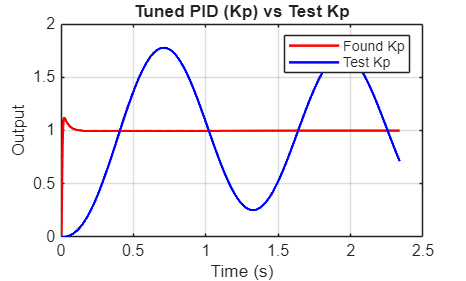

Closed-loop metrics: Ts=0.0801 s, OS=11.87%, Tr=0.0103 s, Ess=0.000%



D_test   = Kp_test + Ki_test/s + Kd_test * (-p*s/(s - p));

% Closed loop TF and applyong step
Tcl_test = feedback(G*D_test, H);
y_test  = step(Tcl_test, t_plot);


% Plotting
figure;
plot(t_plot, y_found, '-r', 'LineWidth', 1.5); hold on;
plot(t_plot, y_test,  '-b', 'LineWidth', 1.5);
grid on;

xlabel('Time (s)');
ylabel('Output');
title('Tuned PID (Kp) vs Test Kp');
legend('Found Kp', 'Test Kp');

## Plotting the experimental data, tuned, and untuned PID

y_untuned = step(sys_tf21, t);

figure;
plot(t, y_exp, 'k', 'LineWidth', 2); hold on;
plot(t, y_untuned, '--r', 'LineWidth', 1.5);
plot(t, y_tuned, '-b', 'LineWidth', 1.5);
grid on;

xlabel('Time (s)');
ylabel('Output');
title('Experimental vs Untuned vs Tuned Closed-Loop');
legend('Experimental Data', 'Untuned PID', 'Tuned PID');
